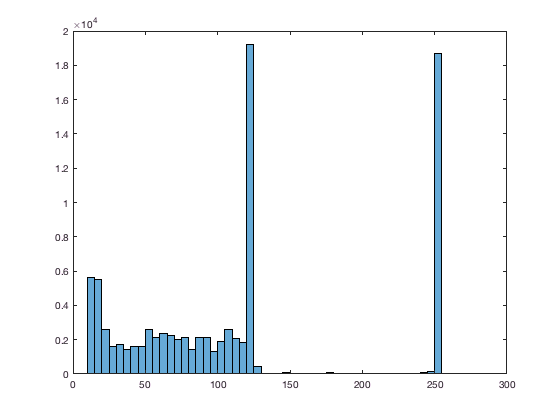

clc
clear all
close all

Im = imread('globe.png');
Im_size(:)=size(Im);%Gather size data of image
X=Im_size(1);%Save the x dimension
Y=Im_size(2);%Save the Y dimension

while X > 300
    Im = imresize(Im,.5);
    Im_size(:)=size(Im);%Gather size data of image
    X=Im_size(1)%Save the x dimension
    Y=Im_size(2)%Save the Y dimension
end

histogram(Im)


%Add or remove thresholds in the line below according to the histogram
%Globe threshs: 0,117,200
thresh = [117,200]

thresh =    117   200


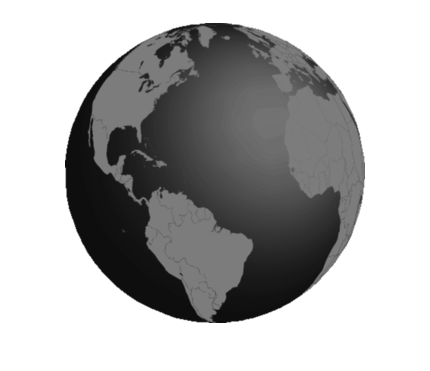


%Convert the image based on the thresholds
Im_Shaded = imquantize(Im,thresh);

%fileID = fopen('Untitled.txt','wt');
%fprintf(fileID,'%f',Im_Shaded);
%fclose(fileID);

imshow(Im);

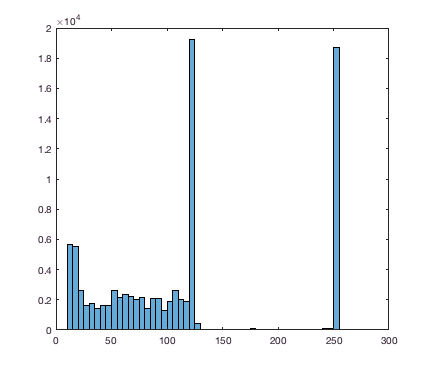

histogram(Im)

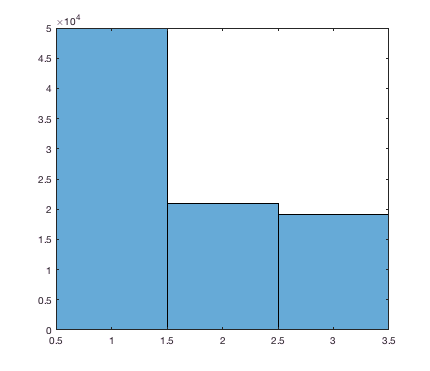

histogram(Im_Shaded)

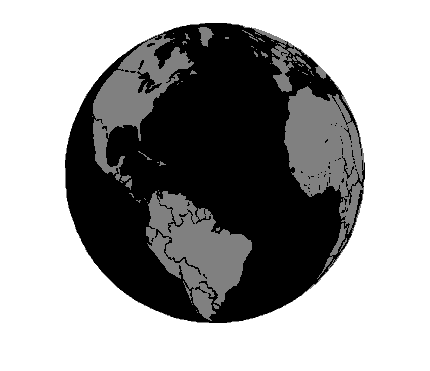

imshow(Im_Shaded,[])

%Now isolating each shade as a seperate b and w image
max_value=max(Im_Shaded(:))

max_value = 3

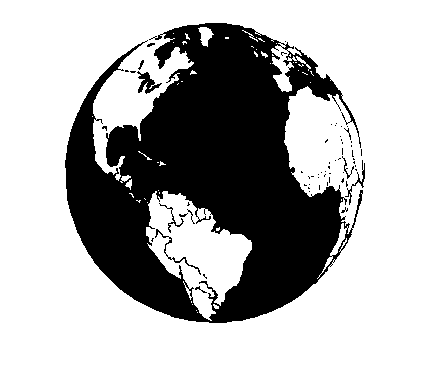


    Im_array_1=im2bw(Im,thresh(1)/255);
    Im_array_2=~im2bw(Im,thresh(2)/255);
    Im_array_3=im2bw(Im,thresh(2)/255);
    
    imshow(Im_array_1);

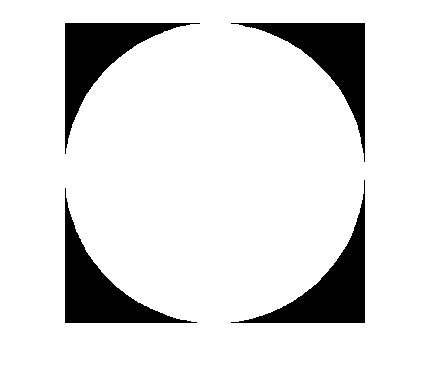

    imshow(Im_array_2);

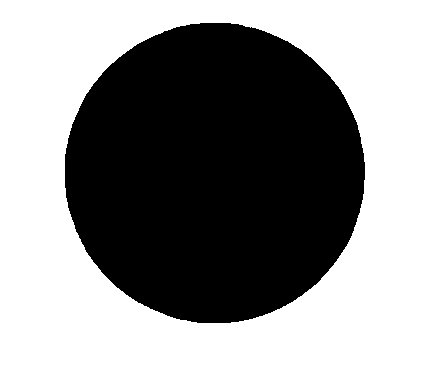

    imshow(Im_array_3);

%-------------------------------------------
num_objects_1 = max(max(bwlabel(Im_array_1)))

num_objects_1 = 50

num_objects_2 = max(max(bwlabel(Im_array_2)))

num_objects_2 = 1

num_objects_3 = max(max(bwlabel(Im_array_3)))

num_objects_3 = 4

%Converts the different shades into outlines
Im_array_outline_3 = bwmorph(Im_array_3,'remove');
Im_array_outline_2 = (bwmorph(bwmorph(Im_array_2,'remove'),'clean'));
Im_array_outline_1 = bwmorph(Im_array_1,'remove')-bwmorph(Im_array_3,'remove')-bwmorph(Im_array_2,'remove');

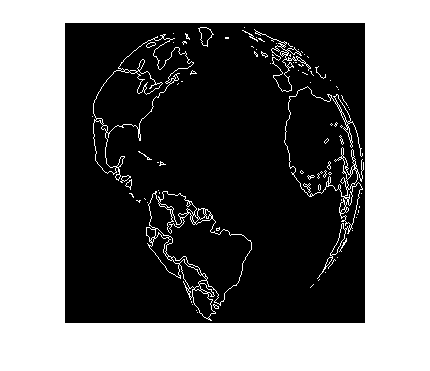

imshow(Im_array_outline_1)

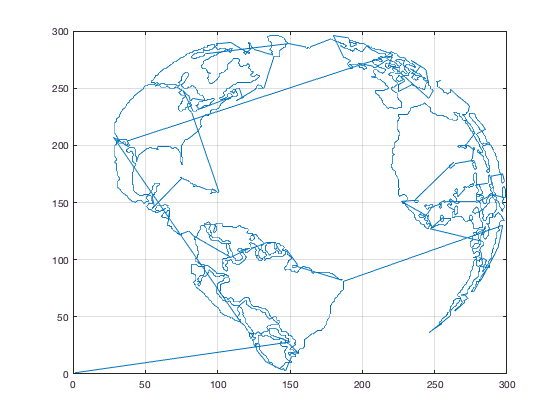


Im_array_rot_1 = imrotate(Im_array_outline_1,270);
[x_moves, y_moves, x_coor, y_coor, X_1, Y_1] = image_2_machine(Im_array_rot_1,X,Y);

figure
plot(x_coor,y_coor)
grid on

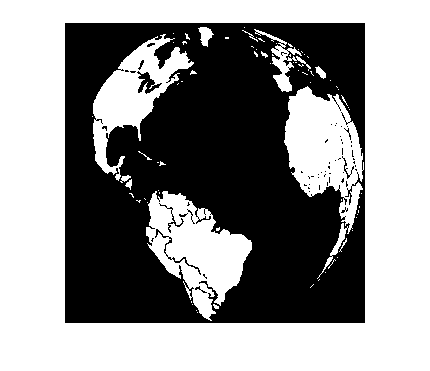

Im_please_work = Im_array_1 - Im_array_3 - Im_array_outline_2;

imshow(Im_please_work)

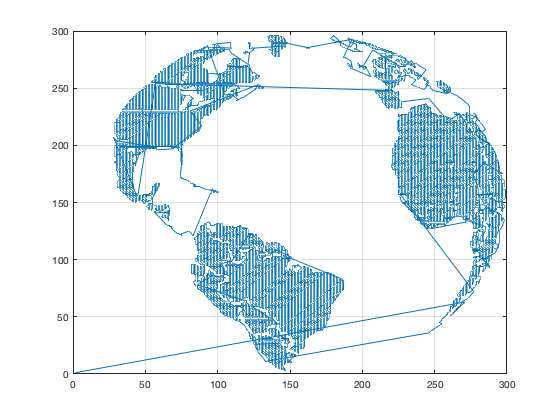


Im_array_rot_1 = imrotate(Im_please_work,270);
[x_moves_2, y_moves_2, x_coor_2, y_coor_2, X_2, Y_2] = image_2_machine(Im_array_rot_1,X_1,Y_1);

figure
plot(x_coor_2,y_coor_2)
grid on

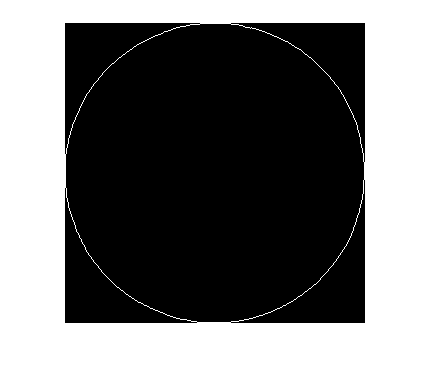

imshow(Im_array_outline_2)

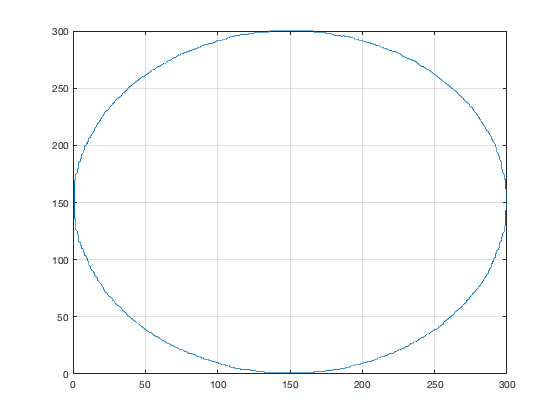


Im_array_rot_2 = imrotate(Im_array_outline_2,270);
[x_moves_3, y_moves_3, x_coor_3, y_coor_3, X_3, Y_3] = image_2_machine(Im_array_rot_2,X_2,Y_2);

figure
plot(x_coor_3,y_coor_3)
grid on

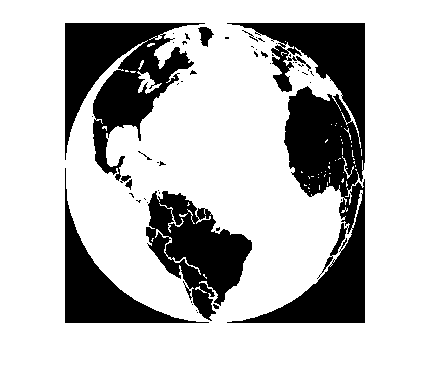

Im_please_work_2 = Im_array_2-Im_array_1;

imshow(Im_please_work_2)

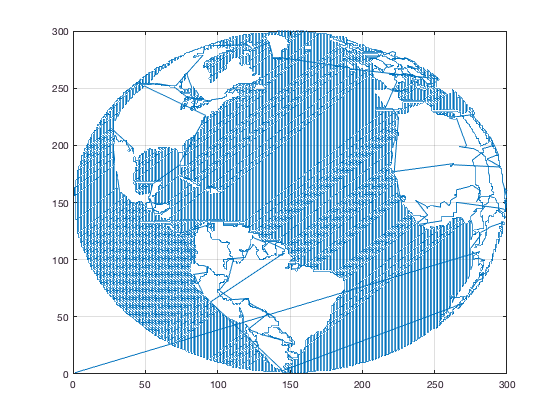


Im_array_rot_2 = imrotate(Im_please_work_2,270);
[x_moves_4, y_moves_4, x_coor_4, y_coor_4, X_4, Y_4] = image_2_machine(Im_array_rot_2,X_3,Y_3);

figure
plot(x_coor_4,y_coor_4)
grid on

%[x_move_3, y_move_3, final_x_3, final_y_3, num_steps_3 ] = conv_to_moves( Im_array_outline_1, final_x_2, final_y_2);

num_steps = length(x_moves_4)+length(x_moves_3)+length(x_moves_2)+length(x_moves)

num_steps = 26044


fileID = fopen('image_data.h','w');
fprintf(fileID,'int num_of_steps = ');
fprintf(fileID,'%1i;\n\n',num_steps);

fprintf(fileID,'//Move list from origin point (0,0) \n');
fprintf(fileID,'//Every four numbers is (XL, XR, YD, YU) \n');
fprintf(fileID,'int move_list[] = {');

for i = 1:length(x_moves_3)
    if x_moves_3(i) < 0
    fprintf(fileID,' %1i, 0',0-x_moves_3(i));
    else
    fprintf(fileID,' 0, %1i',x_moves_3(i));
    end
        fprintf(fileID,',');
    if y_moves_3(i) < 0
    fprintf(fileID,' %1i, 0',0-y_moves_3(i));
    else
    fprintf(fileID,' 0, %1i',y_moves_3(i));
    end
    if (num_steps ~= i)

        fprintf(fileID,',');
    end
end

Index exceeds matrix dimensions.


fprintf(fileID,'};\n');

fclose(fileID);

type image_data.h
